# PV Orientation

clear all;
close all;

## Grundgerüst

%Umwandlung von dem Abgabedatum
%datum = datetime('2024-10-17');
%doy = day(datum, "dayofyear");
doy= 1:1:365;
% Berechne delta in Grad
delta = 23.45 * sind((360/365) * (doy + 284));
% Zeit
t_h= 1:0.5:24;
t_j = 1:1:365;
% Standortbreite in Grad für IBK
phi = 47.27;

% Berechne den Winkel alpha für verschiedene Stunden t
% Alpha = Höhenwinkel
alpha = @(t) asind((sind(phi) * sind(delta(291))) + (cosd(phi) * cosd(delta(291)) * cosd(15*(t - 12))));
alpha_values_h = alpha(t_h)

alpha_values_h =   -51.2896  -48.7884  -45.5373  -41.7016  -37.4266  -32.8316  -28.0118  -23.0435  -17.9894  -12.9030   -7.8321   -2.8224    2.0804    6.8281   11.3682   15.6423   19.5850   23.1233   26.1783   28.6685   30.5159   31.6542   32.0390   31.6542   30.5159   28.6685   26.1783   23.1233   19.5850   15.6423   11.3682    6.8281    2.0804   -2.8224   -7.8321  -12.9030  -17.9894  -23.0435  -28.0118  -32.8316  -37.4266  -41.7016  -45.5373  -48.7884  -51.2896  -52.8761  -53.4210


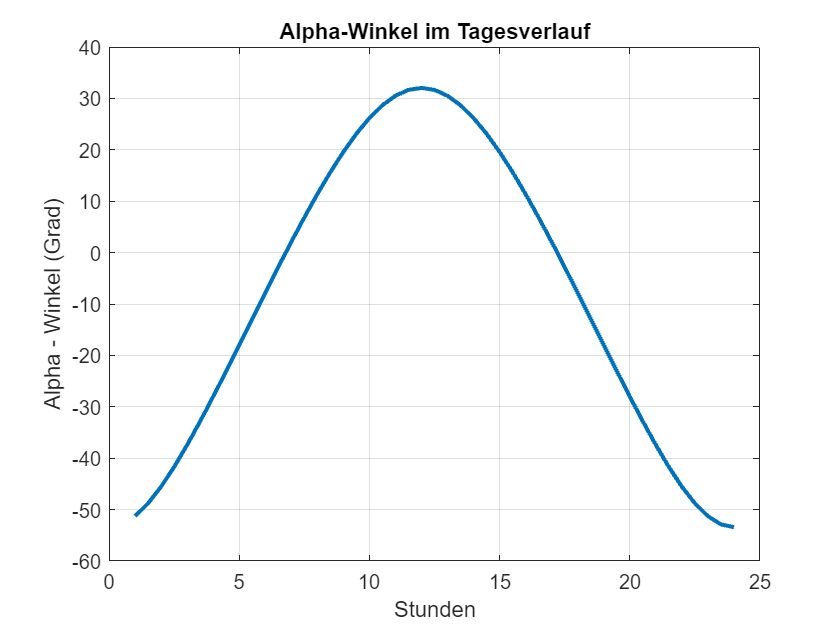

figure;
plot(t_h, alpha_values_h, 'LineWidth', 2);
xlabel('Stunden');
ylabel('Alpha - Winkel (Grad)');
title('Alpha-Winkel im Tagesverlauf');
grid on;

% %Methode2
% for t = 1:24
%      alpha(t) = asind((sind(phi) * sind(delta)) + (cosd(phi) * cosd(delta) * cosd(15*(t - 12))));
% end


%Sonnenaufgang
time_up = -(acosd(-tand(phi)*tand(delta(1))) / 15) + 12

time_up = 7.8248


time_up_dateformat= datestr( time_up/24, "HH:MM:SS")

time_up_dateformat = '07:49:29'

%Sonnenuntergang
time_down = (acosd(-tand(phi)*tand(delta(1))) / 15) + 12

time_down = 16.1752

time_down_dateformat= datestr( time_down/24, "HH:MM:SS");

%Uptime Sonne
% Umwandlung in duration-Objekte

durationUp = duration(time_up_dateformat, 'InputFormat', 'hh:mm:ss')

durationUp = duration
   07:49:29



durationDown = duration(time_down_dateformat, 'InputFormat', 'hh:mm:ss')

durationDown = duration
   16:10:30



% Berechnung der Differenz
deltaDayTime = durationDown - durationUp

deltaDayTime = duration
   08:21:01



decimalHours = time_down-time_up

decimalHours = 8.3503

% Umwandlung in ein duration-Objekt
timeDuration = hours(decimalHours);

% Umwandlung in das Format "HH:MM:SS"
formattedTime = char(timeDuration);

% Ausgabe
disp(formattedTime);

8.3503 hr


%Azimut
azimut_winkel = @(t,alpha)  real(acosd((sind(delta)-sind(alpha(t)).*sind(phi)) ./ (cosd(alpha(t)).*cosd(phi))));
azimut_wikel_value_h = azimut_winkel(t_h,alpha)

Arrays have incompatible sizes for this operation.

Error in Main>@(t,alpha)real(acosd((sind(delta)-sind(alpha(t)).*sind(phi))./(cosd(alpha(t)).*cosd(phi)))) (line 56)
azimut_winkel = @(t,alpha)  real(acosd((sind(delta)-sind(alpha(t)).*sind(phi)) ./ (cosd(alpha(t)).*cosd(phi))));

Related documentation

figure;
plot(t_h, azimut_wikel_value_h, 'LineWidth', 2);
xlabel('Stunden');
ylabel('Azimut-Winkel (Grad)');
title('Azimut-Winkel im Tagesverlauf');
grid on;
%Vektor zur Sonne

